# Cell segmentation - Part 2

## 0. Introduction

This tutorial aims to help biomedical students and researchers do some basic image processing and analysis using MATLAB. After this tutorial, one should be able to

- Import and Visaulize images

- Filter images based on their texture.

- Segment images.

- Analyze segmented images

To be able to run this tutorial, the [Image Proceessing Toolbox](https://www.mathworks.com/products/image.html) is required. If there is no MATLAB license available, a free trial here can be [downloaded here](https://www.mathworks.com/campaigns/products/trials.html).

### Further learning

Additional resources related to biomedical image processing applications with MATLAB 

- [Get Started with Image Processing Toolbox](https://www.mathworks.com/help/images/getting-started-with-image-processing-toolbox.html)

- [Hands-on Image Processing Tutorial](https://www.mathworks.com/learn/tutorials/image-processing-onramp.html)

- Other Projects on Medical Image Processing on [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange?q=medical+image+processing) 

What if we have to segment an image which does not have any color information?

Our aim is to detect the properties of the **cells** in the image below. Courtesy:  ([http://www.cellimagelibrary.org/images/12626](http://www.cellimagelibrary.org/images/12626)) 

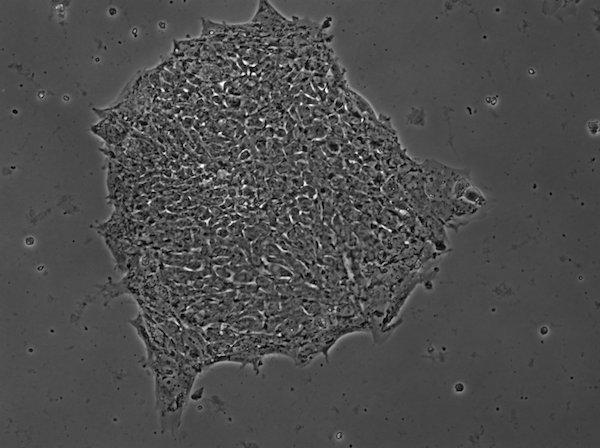

Some house-keeping at the beginning

% To erase all previous variables from MATLAB's memory 
clear all 

% To close all previous figures
close all 

% To clear the screen
clc

% To add the path of files that we need
addpath('Required files/')

## 1. Texture filtering

A texture could be subjectively described by terms such as **rough**, **smooth**, **bumpy**, etc. and refers to variations in the intensity values.

Texture segmentation refers to the characterization of regions in an image by their texture content. 

### 1a. Importing the image

- Importing the image. Use [`imread`](https://www.mathworks.com/help/matlab/ref/imread.html)

- Display the image. Use [`imshow`](https://www.mathworks.com/help/images/ref/imshow.html).

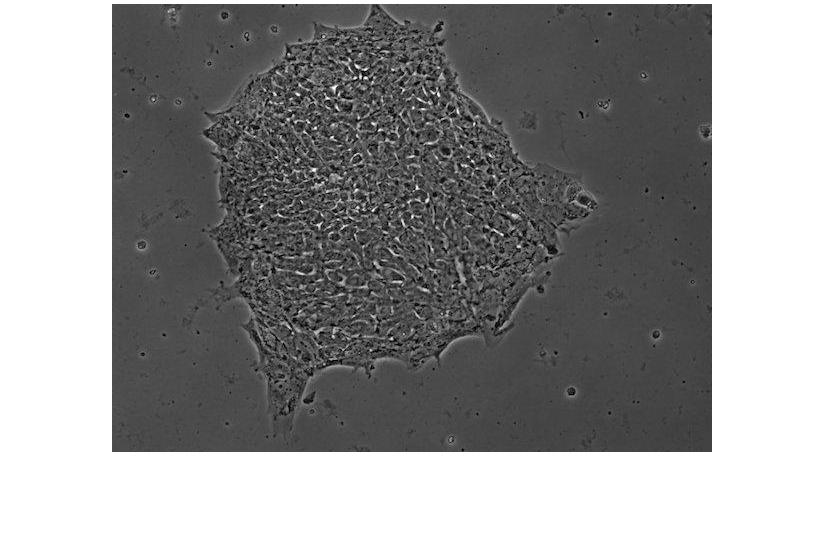

% Reading the image
I = imread('cell2.jpg');

% Displaying the image
figure
imshow(I)

### 1b. Applying Filters

The Image Processing Toolbox provides a number of texture analysis functions.

- Apply the range filter. Use [`rangefilt`](https://www.mathworks.com/help/images/ref/rangefilt.html)

Each output pixel contains the range value (maximum value − minimum value) of the 3-by-3 neighborhood around the corresponding pixel in the input image `I`

- Apply the standard deviation filter. Use [`stdfilt`](https://www.mathworks.com/help/images/ref/stdfilt.html) 

Each output pixel is the standard deviation of the 3-by-3 neighborhood around the corresponding input pixel in the input image `I`

- Apply the entropy filter. Use [`entropyfilt`](https://www.mathworks.com/help/images/ref/entropyfilt.html)

Each output pixel contains the entropy value of the 9-by-9 neighborhood around the corresponding pixel in the input image `I.`

Entropy is a statistical measure of randomness that can be used to characterize the texture of the input image.

Entropy is defined as `-sum(p.*log2(p))`, where `p` contains the normalized histogram counts returned from [`imhist`](https://www.mathworks.com/help/images/ref/imhist.html)`.`

% Apply rangefilt
I_range = rangefilt(I);

% Apply stdfilt
I_std = stdfilt(I);

% Apply entropyfilt
I_entropy = entropyfilt(I);

- Plot the original image and all the filtered images together. Use `subplot`

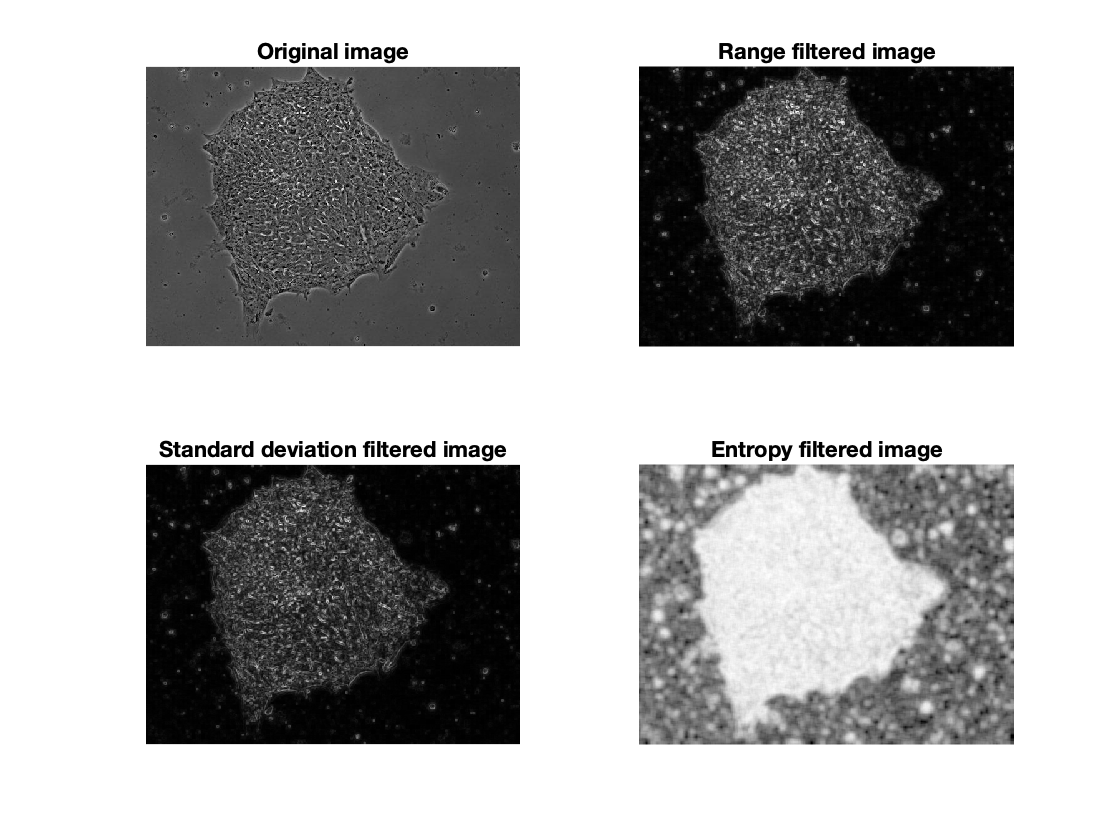


% Plot the figures in a 2x2 matrix
figure;

subplot(2,2,1); 
imshow(I,[]);
title('Original image')

subplot(2,2,2);
imshow(I_range,[]);
title('Range filtered image')

subplot(2,2,3);
imshow(I_std,[]);
title('Standard deviation filtered image')

subplot(2,2,4);
imshow(I_entropy,[]);
title('Entropy filtered image')

The entropy filtered image seem to better highlight the presense of the amoeba. 

## 2. Threshold and Binarize

- Rescale the intensity values to lie **between 0 and 1.** Use [`rescale`](https://www.mathworks.com/help/matlab/ref/rescale.html)`.` We do this because `imbinarize`, to be used later, expects pixel values to be in the range [0, 1].

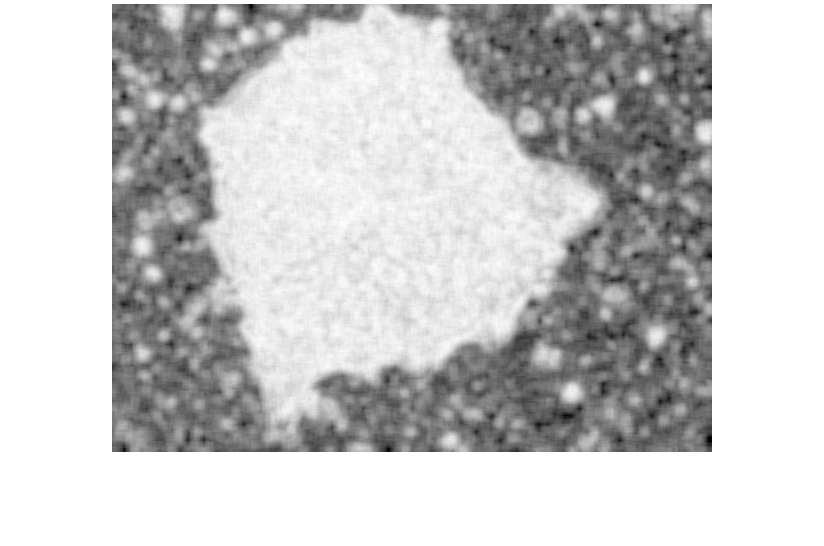

I_scaled = rescale(I_entropy);

figure;
imshow(I_scaled);

### **2a. Binarize the image**

- Binarize the intensity values to be either** 0 and 1.** Use [`imbinarize`](https://www.mathworks.com/help/images/ref/imbinarize.html)

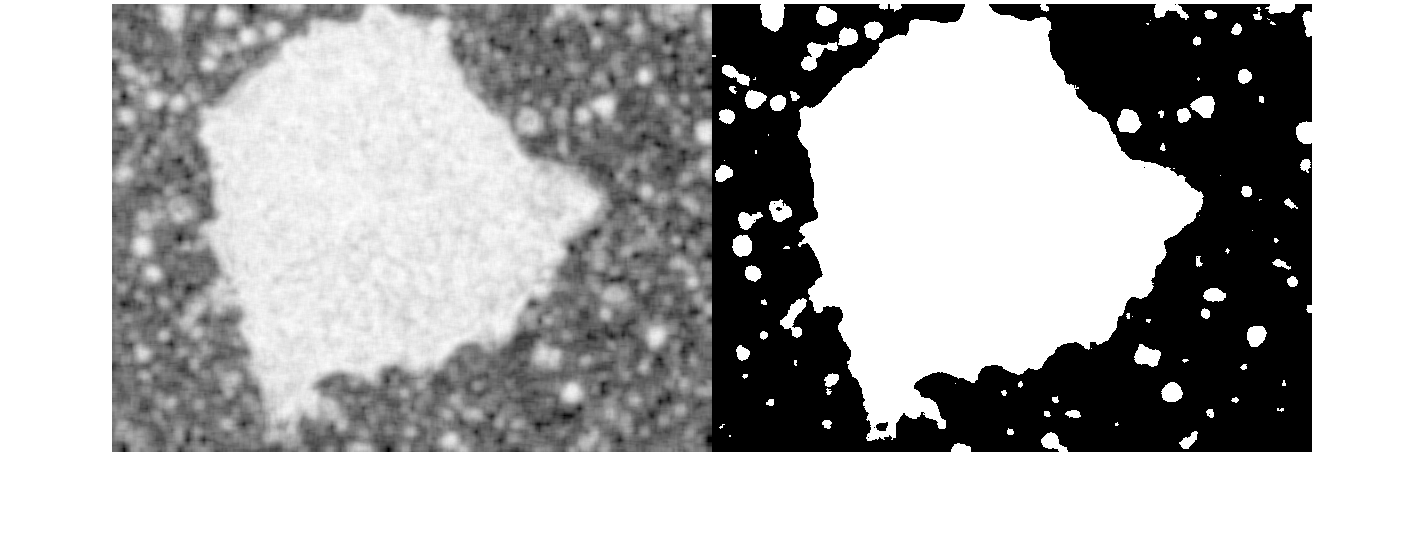

% % Finding binary image
I_thresh = imbinarize(I_scaled);

% Displaying the orginial and binary image side by side
figure
imshowpair(I_scaled,I_thresh,'montage');

## 3. Morphological operation

[Morphological operations](https://www.mathworks.com/help/images/morphological-filtering.html) include many image processing operations based on their shapes. Each pixel in the image is adjusted based on the value of other pixels in its neighborhood.

Examples of functions are: `imdilate`, `imerode`, `imfill`, `imopen`, `imclose`, etc.

### 3a. **Fill the holes**

- Fill the holes, of any, inside connected regions. Use [`imfill`](https://www.mathworks.com/help/images/ref/imfill.html)

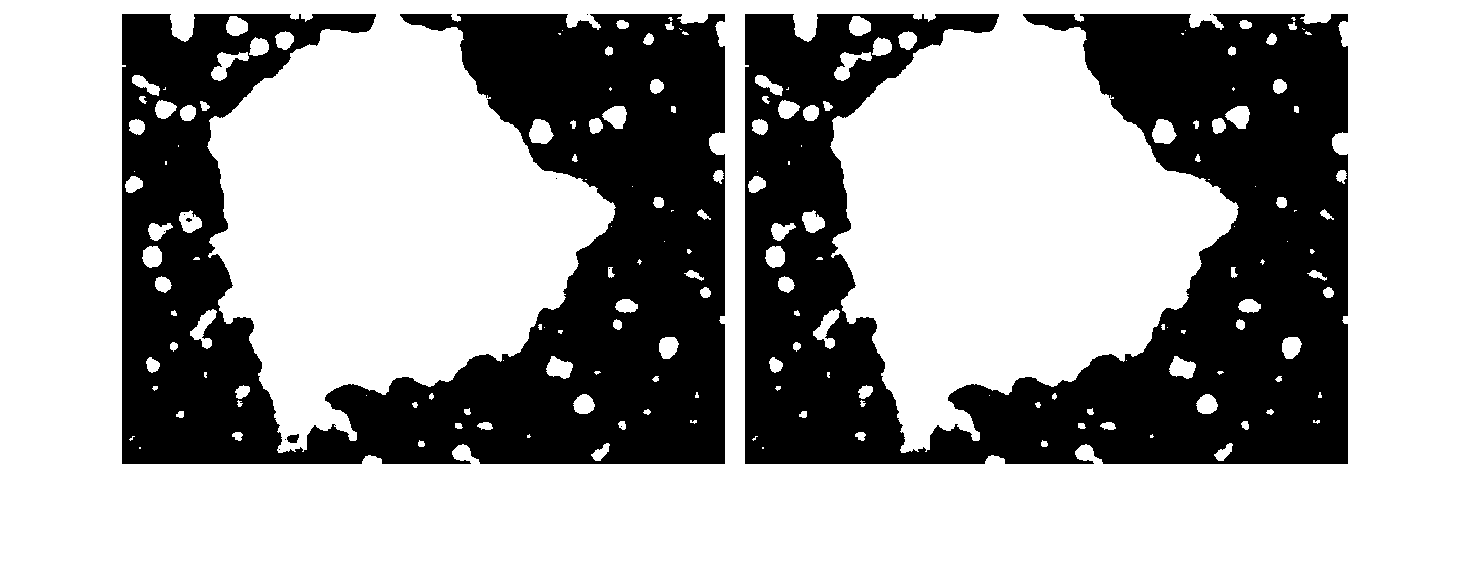

% Create an image with filled holes
I_filled = imfill(I_thresh,'holes');

% Displaying the orginial and image with filled holes side by side
figure
montage({I_thresh,I_filled},'BorderSize',10,"BackgroundColor",'w');

### 3b. Remove small areas

- Extract the connected regions with 3 largest areas. Use [`bwpropfilt`](https://www.mathworks.com/help/images/ref/bwpropfilt.html)

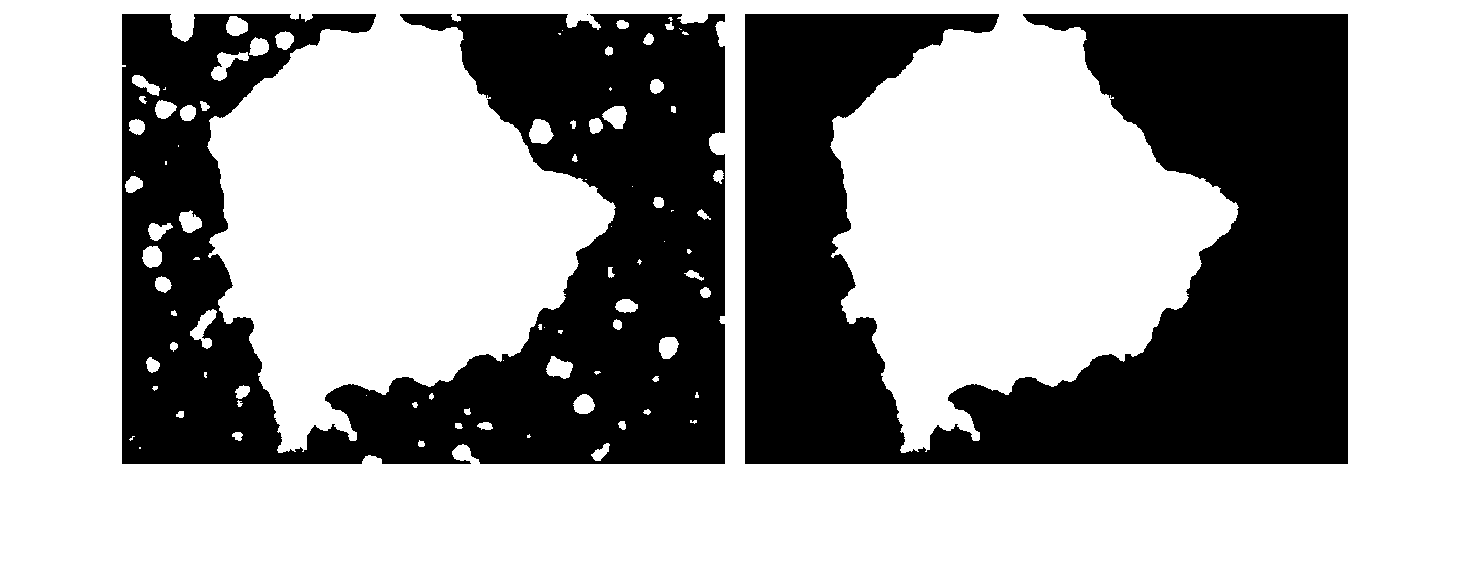

% Finding image with 3 largest areas
I_largest = bwpropfilt(I_filled, 'area', 1, 'largest');

% Displaying the orginial and image with 3 largest areas side by side
figure
montage({I_filled,I_largest},'BorderSize',10,'BackgroundColor','w');

We can use the above image `I_largest` as the mask for the location of the amoeba cells.

### 3d. Add boundaries

- Draw a boundary around each segmented object. Use [`bwboundaries`](https://www.mathworks.com/help/images/ref/bwboundaries.html)

bounds = bwboundaries(I_largest);

- Visualise the original image with boundaries. Use [`visboundaries`](https://www.mathworks.com/help/images/ref/visboundaries.html)

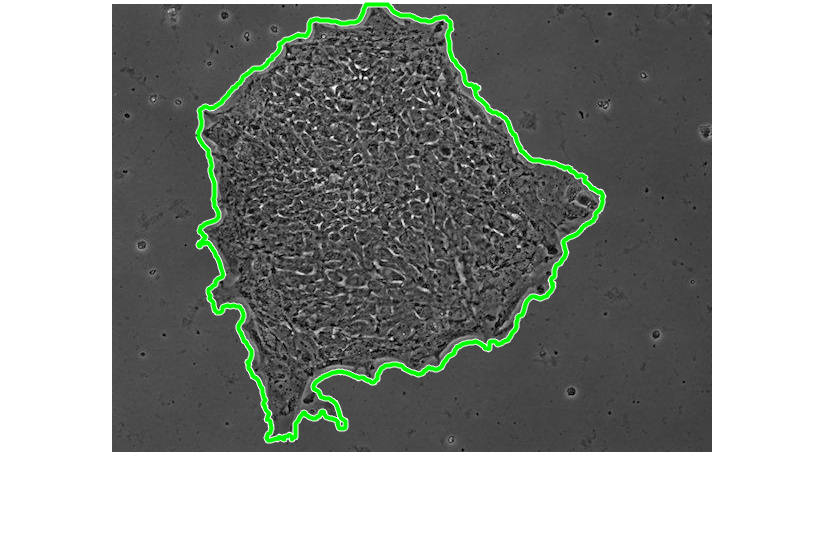

% Plot the original image
figure
imshow(I)

% Plot the boundaries om top of the original image
hold on
visboundaries(bounds, 'color', 'g')
hold off

*Copyright 2020 The MathWorks, Inc*